clearvars -except current_faulty current_healthy time_healthy time_faulty current_fea_healthy time_fea_halthy current_fea_faulty time_fea_faulty PSD_dB_fea_h PSD_dB_fea_f PSD_dB PSD_dB_f f f2 f_fea_h f_fea_f;
clc;
clear all;
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload = readtable(fullpath, 'Range', 'A:B'); 
dataMatrix = table2array(data_noload);
current_fea_healthy = dataMatrix(:,2);
time_fea_healthy = dataMatrix(:,1);
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
dataMatrixx = table2array(data_noload_2);
current_fea_faulty = dataMatrixx(:,2);
time_fea_faulty = dataMatrixx(:,1);


##  30 Cycles for Steady State:

threshold_time = 1;
num_zero_crossings = 60;
[time_lcf, current_lcf] = plot_cycles(time_fea_faulty, current_fea_faulty, threshold_time, num_zero_crossings);
[time_lch, current_lch] = plot_cycles(time_fea_healthy, current_fea_healthy, threshold_time, num_zero_crossings);

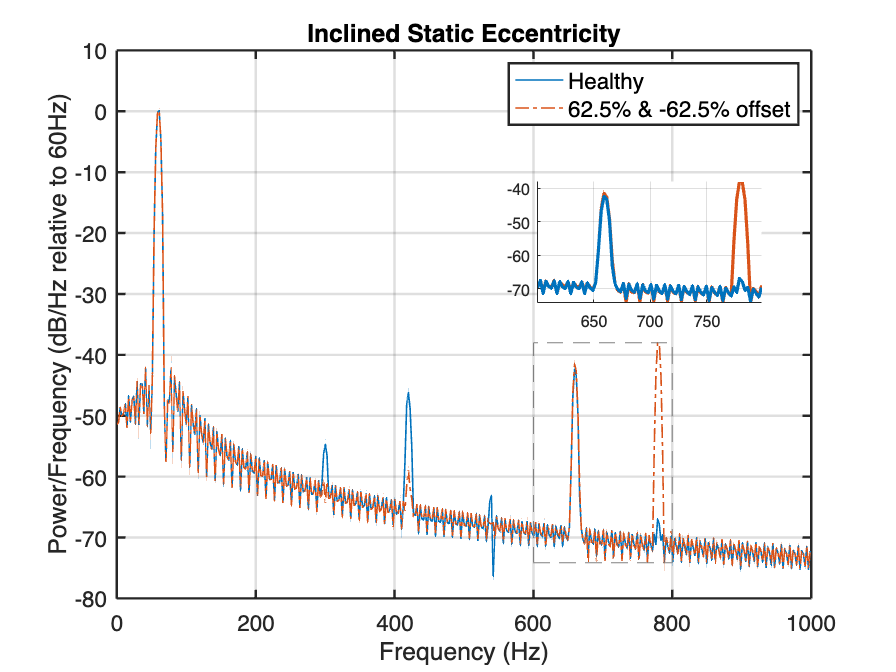

segment_fraction = 0.5;

% First dataset calculations
[f_fea_h, PSD_dB_fea_h, P_at_60Hz] = calculate_psd(time_lch, current_lch, segment_fraction);

% Second dataset calculations
[f_fea_f, PSD_dB_fea_f, P_at_60Hz_2] = calculate_psd(time_lcf, current_lcf, segment_fraction);


plotPSD(PSD_dB_fea_h, f_fea_h, PSD_dB_fea_f, f_fea_f, true, [600, 800]);